clear all

%figure();
%subplot(1,2,1)
%biomass_500_0=zeros(352,352);
run("biomass.m")

biomass_field(1:352,1:352)=0.0;
for cycle=1:51
    
    varname=genvarname(['biomass_' int2str((cycle-1)*100) '_0']);
    biomass_field=eval(varname);
    %biomass_field(:,:)=0.0;
    
    %radial_biomass(1:176)=0.0;
    xmin(cycle)=352;
    xmax(cycle)=1;
    ymin(cycle)=352;
    ymax(cycle)=1;
    %for x=1:352
    %    for y=1:352
    %        biomass=biomass_field(x,y);
    %        Rcurrent=sqrt((x-176)^2+(y-176)^2);
    %        for r=1:176
    %            if Rcurrent>r-1 && Rcurrent <=r
    %                radial_biomass(r)=radial_biomass(r)+biomass;
    %            end
    %        end
    %    end
    %end
    for x=1:351
        for y=1:351
            if biomass_field(x+1,y)>0 && biomass_field(x,y)==0
                if x<xmin(cycle)
                    xmin(cycle)=x;
                end
            end
            if biomass_field(x+1,y)==0 && biomass_field(x,y)>0
                if x>xmax(cycle)
                    xmax(cycle)=x;
                end
            end
            if biomass_field(x,y+1)>0 && biomass_field(x,y)==0
                if y<ymin(cycle)
                    ymin(cycle)=y;
                end
            end
            if biomass_field(x,y+1)==0 && biomass_field(x,y)>0
                if y>ymax(cycle)
                    ymax(cycle)=y;
                end
            end
        end
    end
end

%f1=plot(0.05*[0:500:5000]/24,radius(1:11),LineWidth=2,Color='magenta')
%hold on


h=figure('Units','inches','Position',[0 0 3.25 2.5])

h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 3.2500 2.5000]
       Units: 'inches'

  Show all properties


plot(0.05*100*(0:50)/24,(xmax(:)-xmin(:))*0.01/2,'LineWidth',1)
hold on
plot(0.05*100*(0:50)/24,(ymax(:)-ymin(:))*0.01/2,'LineWidth',1)
%xlim([0,7])
%ylim([0.1,0.5])
xlabel('Time [days]')
ylabel('Colony Radius [cm]')
ax=gca;
ax.FontSize=10

ax =   Axes with properties:

             XLim: [0 10.4167]
             YLim: [0.1500 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1625 0.1611 0.7425 0.7639]
            Units: 'normalized'

  Show all properties


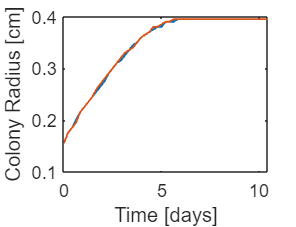

hold on

points=load("ExeprimentsRadius_march2022_R3_dayvsdiameters_well4.txt")

points =          0    4.0700    4.0700
    1.0000    4.8500    4.7700
    2.1000    5.5300    5.6100
    3.1000    6.4300    6.3600
    4.0500    7.0600    6.9400
    5.1000    7.5000    7.3800
    6.2000    7.9900    7.8300
   10.0000    8.6000    8.1300


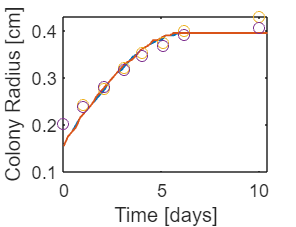

scatter(points(:,1),points(:,2)/20)
hold on
scatter(points(:,1),points(:,3)/20)

f=gcf

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 3.2500 2.5000]
       Units: 'inches'

  Show all properties


exportgraphics(f,"radiusVstime.png",'Resolution', 300)